a = readtable("C:\Users\domin\OneDrive\Raspberry Pico\data_log_2.txt",'Delimiter',';');
a.datetime = datetime(a.datetime,'InputFormat','(yyyy,MM,dd,HH,mm,ss)');
a = table2timetable(a);


%%
%S= timerange(a.datetime(40000),a.datetime(end));
%stackedplot(a(S,:))

%%

a.Properties.VariableNames

ans = 1×25 cell array
    {'Temperatur'}    {'relay_AC_1'}    {'relay_AC_2'}    {'relay_AC_3'}    {'relay_AC_PWM'}    {'Humidity'}    {'Pumpe_5'}    {'Pumpe_4'}    {'Pumpe_3'}    {'EC'}    {'relay_AC_4'}    {'Pumpe_2'}    {'Pumpe_1'}    {'Var15'}    {'Var16'}    {'Var17'}    {'Var18'}    {'Var19'}    {'Var20'}    {'Var21'}    {'Var22'}    {'Var23'}    {'Var24'}    {'Var25'}    {'Var26'}


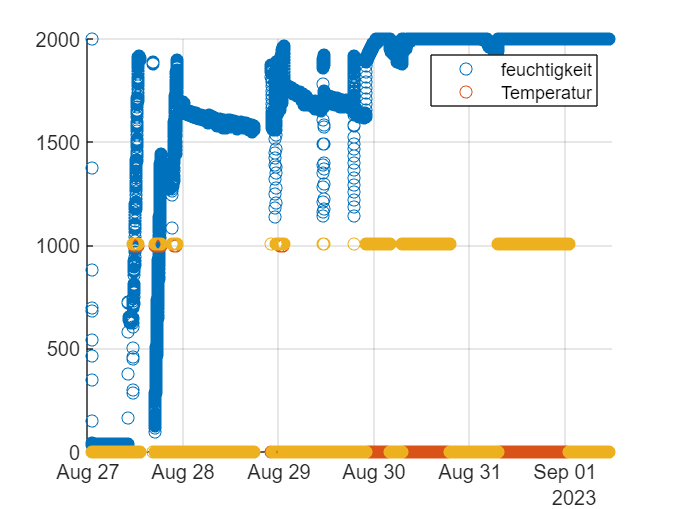


scatter(a.datetime ,a.EC)
hold on
scatter(a.datetime ,a.Pumpe_5*1000)
scatter(a.datetime,a.relay_AC_PWM/65)
legend("feuchtigkeit","Temperatur")
grid on
%%
hold off

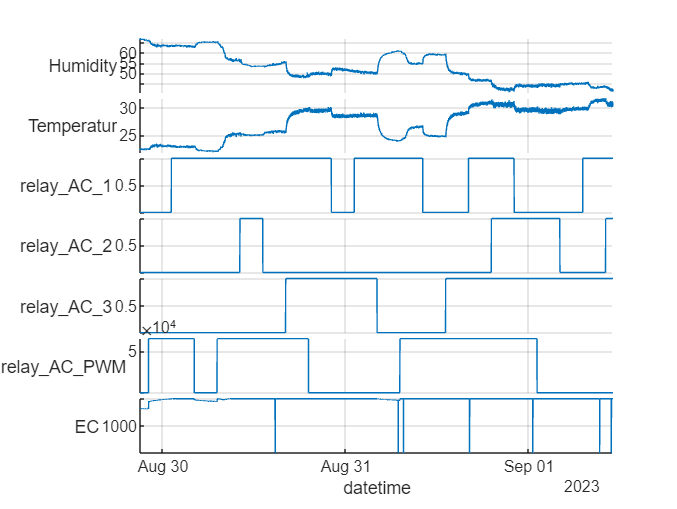


S= timerange(datetime("29-08-2023 21:00:00","InputFormat","dd-MM-yyyy HH:mm:ss"),a.datetime(end));
stackedplot(a(S,:),{'Humidity','Temperatur','relay_AC_1','relay_AC_2','relay_AC_3','relay_AC_PWM','EC'})
grid on

%%
set = a(S,:);


















